# Digital Signal Processing | Lab 01

## Part 1

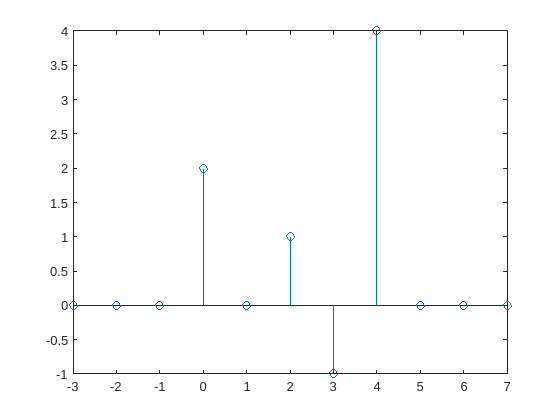

n = -3:7;
x = zeros(length(n),1);
y1 = x; y2 = x; y3 = x; y4 = x;

x(0 <= n & n <= 4) = [2 0 1 -1 4];

figure; stem(n, x);

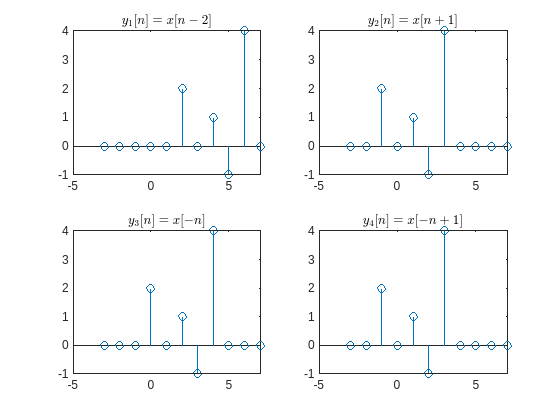

y1(3:end) = x(1:end-2);
y2(1:end-1) = x(2:end);
y3 = fliplr(x);
y4(1:end-1) = y3(2:end);
figure; 
subplot(2,2,1); stem(n, y1); title('$y_1[n] = x[n-2]$','Interpreter','latex');
subplot(2,2,2); stem(n, y2); title('$y_2[n] = x[n+1]$','Interpreter','latex');
subplot(2,2,3); stem(n, y3); title('$y_3[n] = x[-n]$','Interpreter','latex');
subplot(2,2,4); stem(n, y4); title('$y_4[n] = x[-n+1]$','Interpreter','latex');

## Part 2

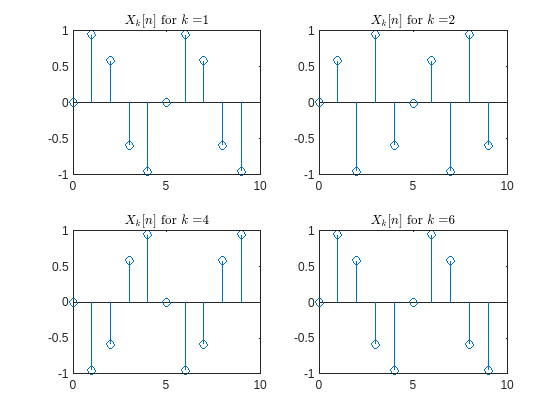

n = 0:9;

k_values = [1,2,4,6];
k_len = length(k_values);

wk_values = 2*pi*k_values/5;

figure;
for i=1:k_len
 k = k_values(i);
 wk = wk_values(i);
 Xk = sin(wk*n);

 subplot(k_len / 2, k_len / 2, i);
 stem(n,Xk); 
 title(['$X_k[n]$ for $k=$', num2str(k)], 'Interpreter','latex');
end

## Part 3

fs = 1000;
t = 0:1/fs:10;
T = 10;

x = sin(2 * pi / T * t);

pwr = sum(x(1, 1:(T * fs)) .^2) / fs / T

pwr = 0.5000

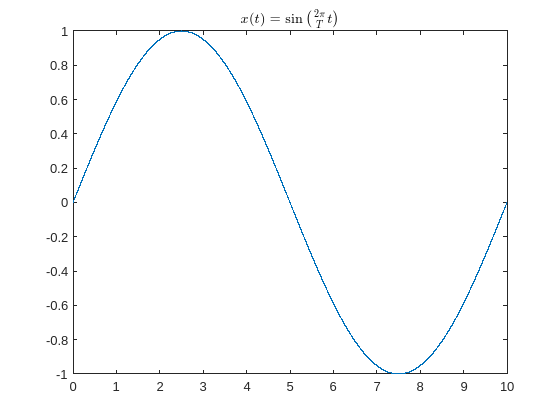

figure;figure;
plot(t, x); title('$x(t) = \sin\left(\frac{2\pi}{T}t\right)$', 'Interpreter', 'latex');

n = 1:12;
x_n = sin(2 * pi / T * n); 

energy = sum(x_n .^2)

energy = 6.2500

pwr = energy / length(n)

pwr = 0.5208

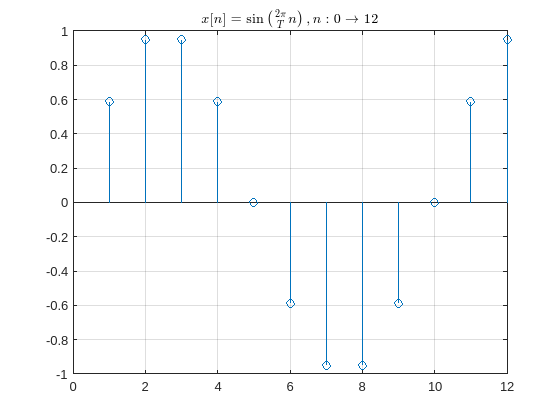

figure;
stem(n, x_n); grid on; title('$x[n] = \sin\left(\frac{2\pi}{T}n\right), n: 0\rightarrow 12$', 'Interpreter', 'latex');

n = 1:1005;

x_n = sin(2 * pi / T * n);
energy = sum(x_n .^2)

energy = 502.5000

pwr = energy / length(n)

pwr = 0.5000

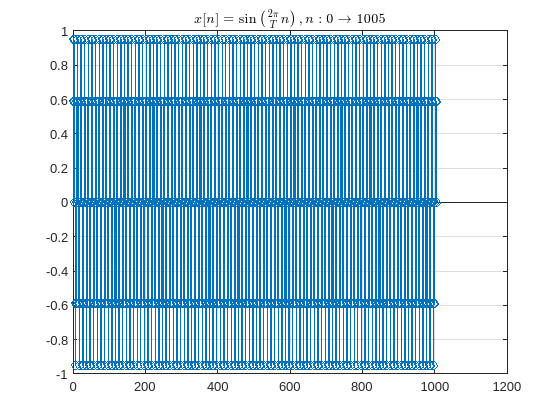

figure;
stem(n, x_n); grid on; title('$x[n] = \sin\left(\frac{2\pi}{T}n\right), n: 0\rightarrow 1005$', 'Interpreter', 'latex');

## **Observation**

As the number of samples (n) increases, the energy increases without bound, and the power approaches the power of the continuous (ideal) signal.